## **Exercise 1**

Find the analytical representation and graph the signals 

**a)**

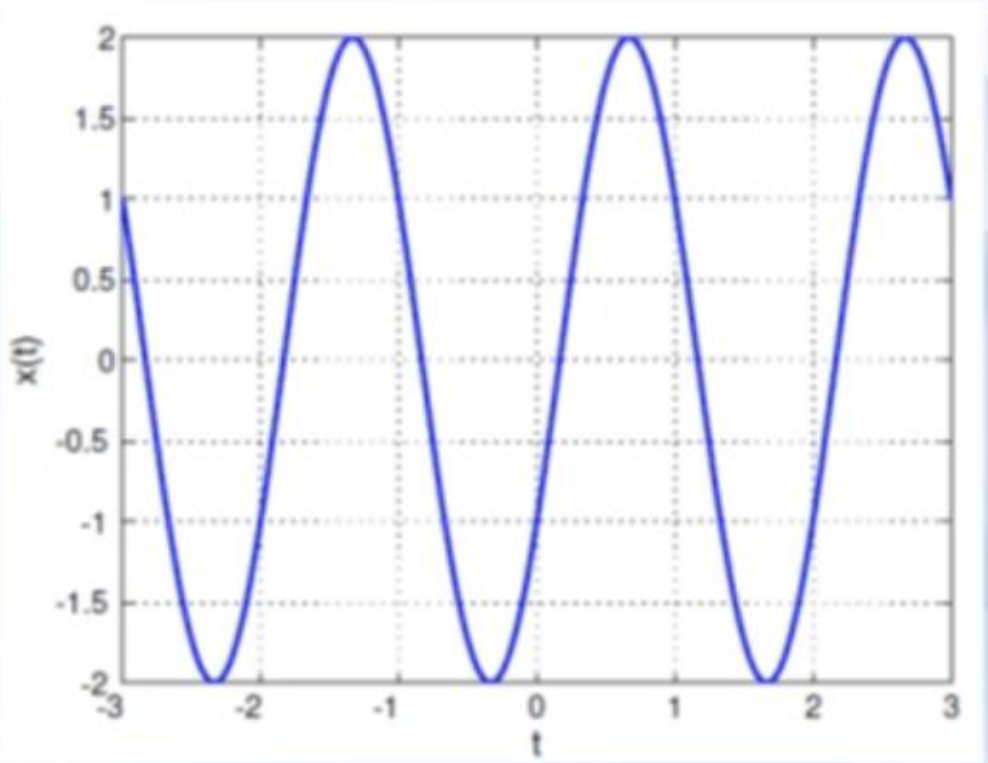

From the graph we can easily see that the signal has the following parameters:

- 
$$A=2$$


- 
$$T=2$$


- 
$$v_{\textrm{offset}} =0$$


- 
$$\varphi =\textrm{asin}\left(x\left(0\right)\right)$$


Hence, the equation of the signal will be:


$$x_1 \left(t\right)=2\sin \left(\pi t+\textrm{asin}\left(\frac{-1}{2}\right)\right)$$


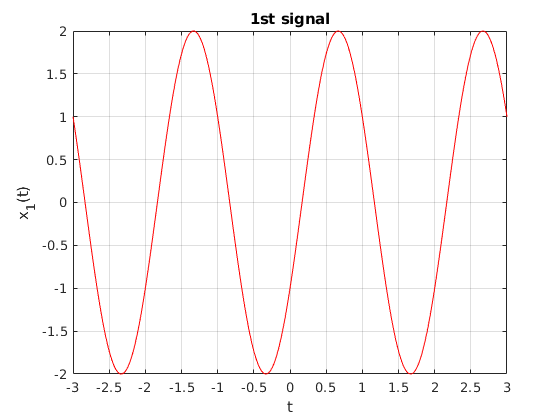

cla;
clear all;
% Generate a linear space for (-3,3) with granularity 1/100
t = -3:0.01:3;
% Create the anonymous function that models the signal
x1 = @(t)(2*sin(pi.*t + asin(-1/2)));
% Plot the signal
plot(t,x1(t), '-r'); 
% Add a grid to the plot and increase the number of X ticks
grid;
xticks(-3:0.5:3);
title("1st signal")
xlabel('t');
ylabel('x_1(t)');

**b) **

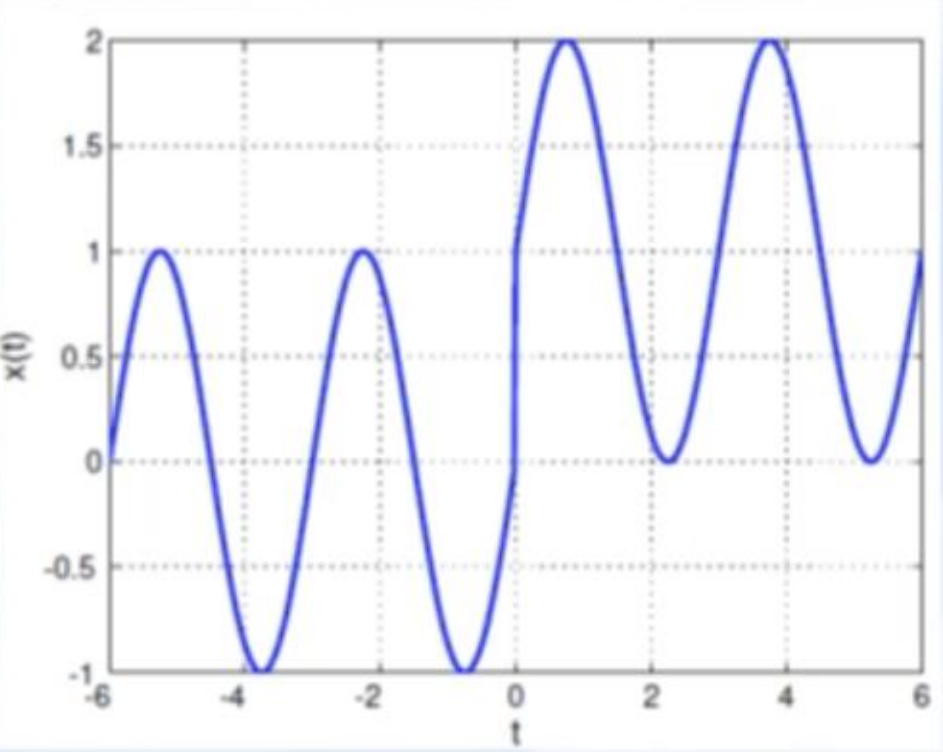

This graph is a combination of two sine signals. Both signals have the same amplitude and period, though the second one has a vertical offset of 1.

The parameters of the signal as a whole are:

- 
$$A=1$$


- 
$$T=3$$


- 
$$v_{\textrm{offset}} =\left\lbrace \begin{array}{ll}
0, & t<0\\
1, & t>0
\end{array}\right.$$


- 
$$\varphi =0$$


The equation of the signal becomes:


$$x_2 \left(t\right)=\sin \left(\frac{2\pi t}{3}\right)+v_{\textrm{offset}}$$


where the vertical offset was previously defined.

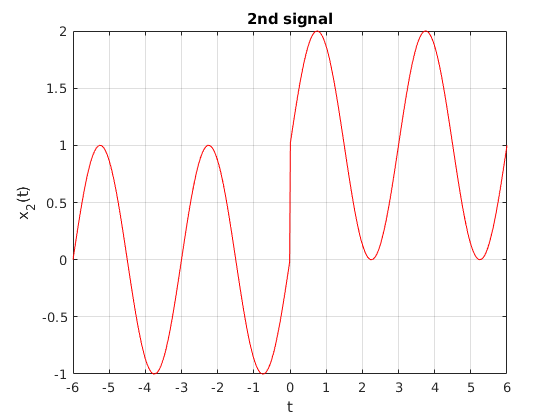

clear all;
% Define the linear space to plot
t = -6:0.01:6;
% Define the function that describes the signal
% We model the vertical offset as a step function that takes the values 0
% or 1, depending on the sign of the input
x2 = @(t)(sin(2*pi.*t/3) + (sign(t)+1)/2);
% Plot the obtained signal
plot(t, x2(t), '-r');
% Add a grid and increase the X ticks 
grid;
xticks(-6:1:6)
title("2nd signal")
xlabel('t');
ylabel('x_2(t)');

**c)**

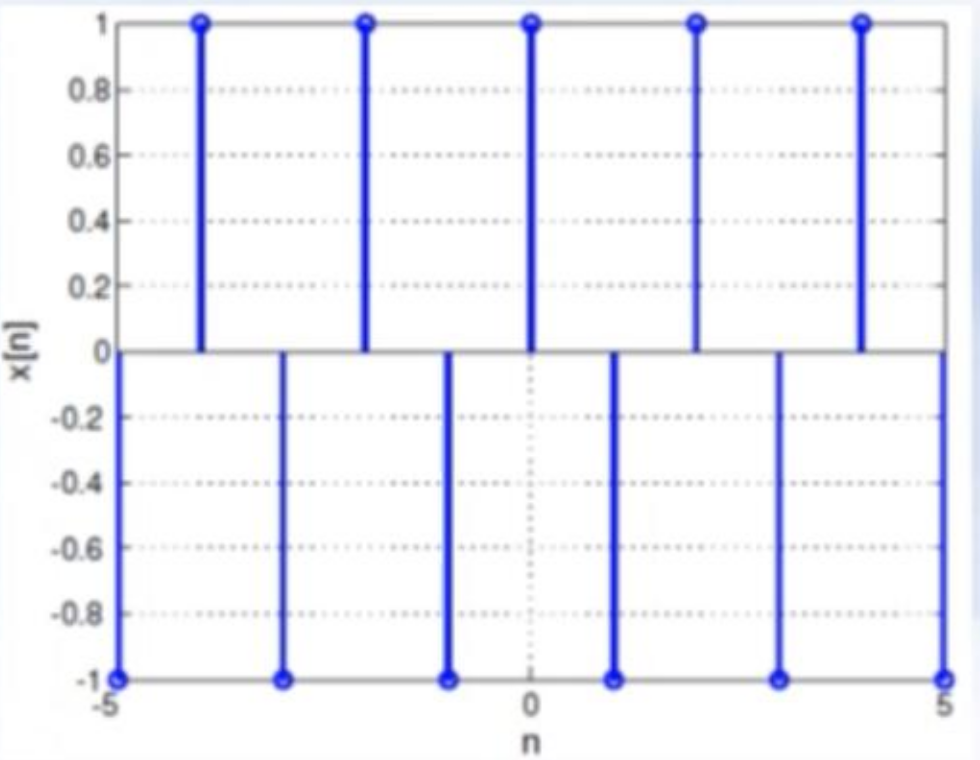

This signal is a discrete one. It is a discrete sample of a cosine signal, having a sampling frequency of 1 second. The parameters of the signal are:

- 
$$A=1$$


- 
$$\varphi =0$$


The period of the signal is 2, so the angular frequency is (according to the formula $\Omega_0 =\frac{2\pi t}{T}$):

- 
$$\Omega_0 =\pi$$


The formula of the signal is:


$$x_3 \left\lbrack n\right\rbrack =\cos \left(\pi n\right)$$


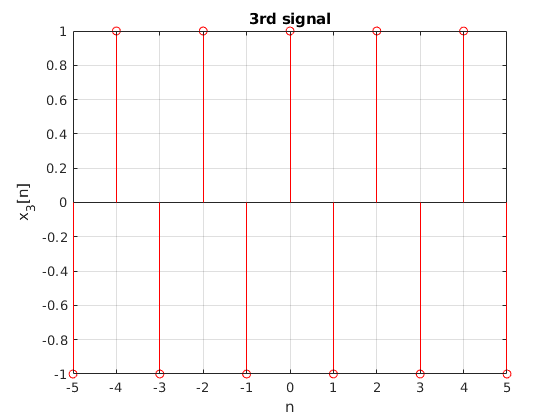

clear all;
% Define the linear space to plot
t = -5:1:5;
% Define the function that describes the signal
% We model the vertical offset as a step function that takes the values 0
% or 1, depending on the sign of the input
x3 = @(n)(cos(pi*n));
% Plot the obtained signal
stem(t, x3(t), '-r');
% Add a grid and increase the X ticks 
grid;
xticks(-5:1:5)
title("3rd signal");
xlabel('n');
ylabel('x_3[n]');

**d)**

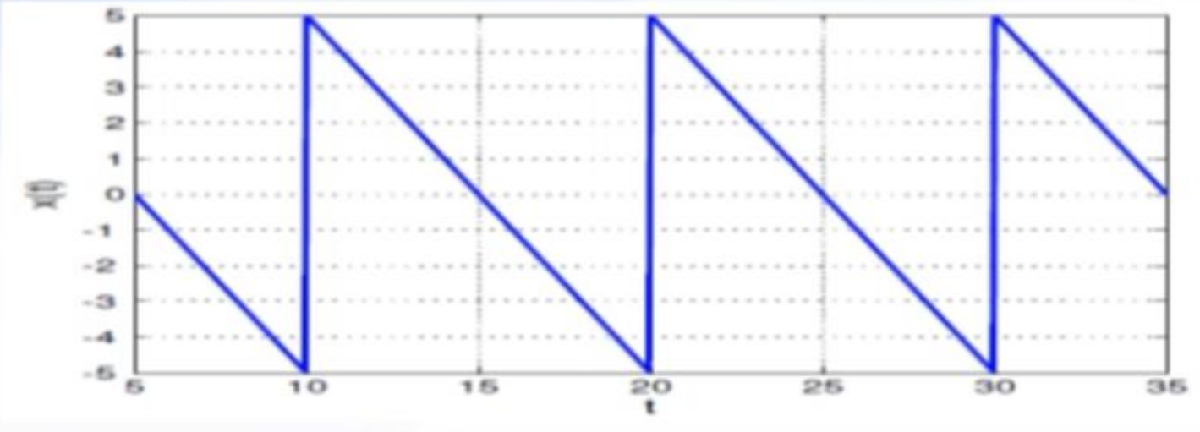

This signal can be represented using the mod function.

Formula:


$$x_4 =-\mathrm{mod}\left(t,10\right)+5$$


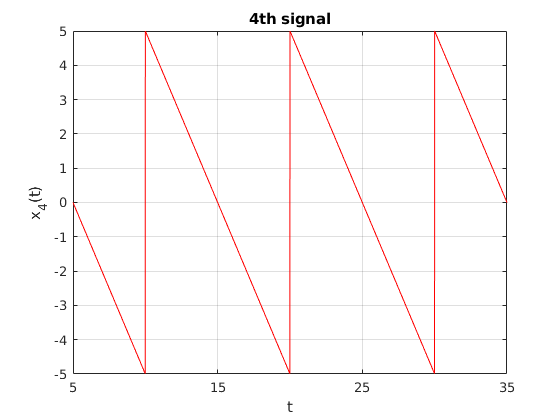

clear all;
% Define the linear space to plot
t = 5:0.01:35;
% Define the function that describes the signal
% We model the vertical offset as a step function that takes the values 0
% or 1, depending on the sign of the input
x4 = @(t)(-mod(t,10) + 5);
% Plot the obtained signal
plot(t, x4(t), '-r');
% Add a grid and increase the X ticks 
grid;
xticks(5:10:35)
title("4th signal");
xlabel('t');
ylabel('x_4(t)');

## **Exercise 2**

Determine which of the following signals are periodic. Plot the signals in Matlab.

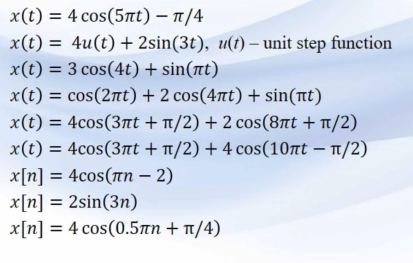

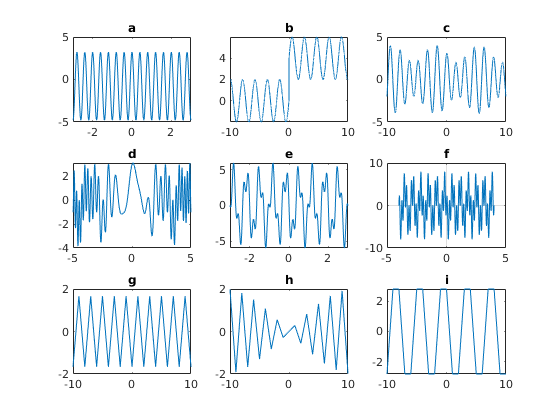

cla;
clear all;
% Define the unit step function
ustep = @(x)((sign(x)+1)/2);
% Define a linear space
t = -10:0.001:10;
n = -10:1:10;

subplot(3,3,1);
t1 = -3:0.01:3;
x1=@(t)(4*cos(5*pi.*t) - pi/4);
plot(t1,x1(t1))
title("a")

subplot(3,3,2);
x2=@(t)(4.*ustep(t)+2*sin(3.*t));
plot(t,x2(t))
title("b")

subplot(3,3,3);
x3=@(t)(3*cos(4.*t) + sin(pi.*t));
plot(t,x3(t))
title("c")

subplot(3,3,4);
t4 = -5:0.01:5;
x4=@(t)(cos(2*pi.*t)+2*cos(t*pi.*t) + sin(pi.*t));
plot(t4,x4(t4))
title("d")

subplot(3,3,5);
t5 = -3:0.01:3;
x5=@(t)(4*cos(3*pi.*t+pi/2)+2*cos(8*pi.*t+pi/2));
plot(t5,x5(t5))
title("e")

subplot(3,3,6);
t6 = -4:0.01:4;
x6=@(t)(4*cos(3*pi.*t+pi/2)+4*cos(10*pi.*t - pi/2));
plot(t6,x6(t6));
title("f")
grid

subplot(3,3,7);
x7=@(t)(4*cos(pi.*t-2));
plot(n,x7(n))
title("g")

subplot(3,3,8);
x8=@(t)(2*sin(3.*t));
plot(n,x8(n))
title("h")

subplot(3,3,9);
x9=@(t)(4*cos(0.5*pi.*t+pi/4));
plot(n,x9(n))
title("i")